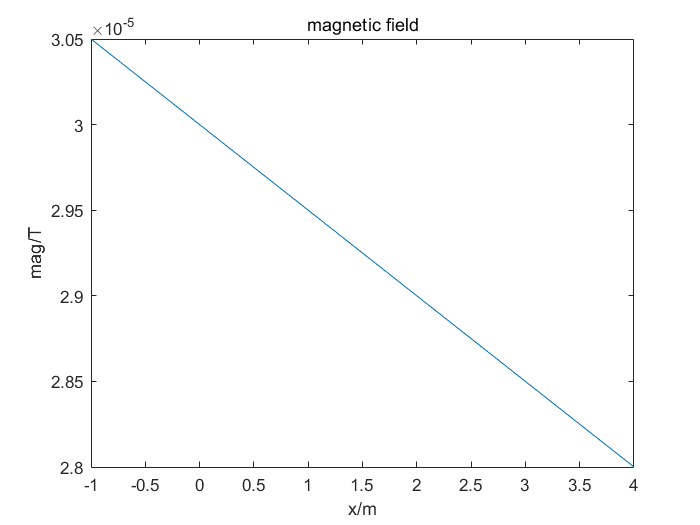

clear all;
close all;
% illustrate magnetic field 
x = -1 : 0.1 : 4;
field1 = arrayfun(@(x) magnetic_model(x), x);
figure;
plot(x, field1)
xlabel('x/m');
ylabel('mag/T');
title('magnetic field');

## System configuration

% simulate IMU noise
sigma_acceleration = 0.05;
% simulate magnetometer noise
sigma_magnetometer = 1e-8;
% spacing of sensors
sensor_spacing = 0.1;
% initial position
init_pos = [0.3, 0, 0];
% velocity 
init_vel = [0.9, 0, 0];
% sampling interval
fs = 100;
dT = 1 / fs;
% monte carlo simulation
N = 100;
% rng(1);

## trajectory

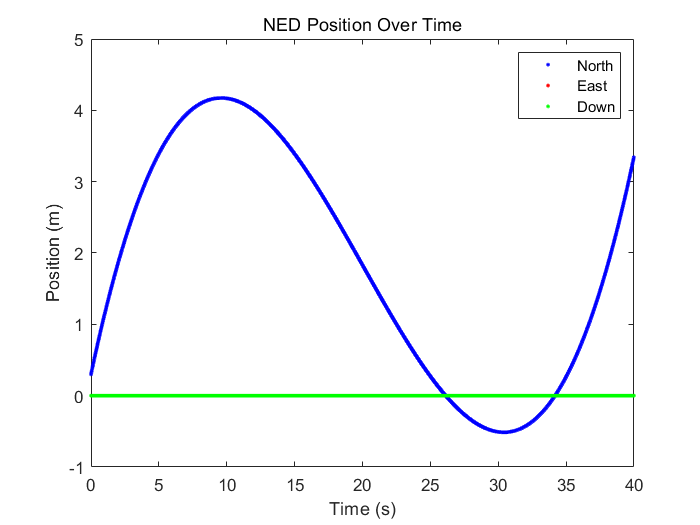

traj = kinematicTrajectory('Position', init_pos, ...
                           'Velocity', init_vel,...
                           'Orientation', quaternion([0 0 0], 'eulerd', 'ZYX', 'frame'));

duration = 40;
numSamples = duration*fs;

% just positive acceleration 
%accBody = [repmat([-0.2, 0, 0], numSamples/2, 1); repmat([-0.3, 0, 0], numSamples/4, 1); repmat([0, 0, 0], numSamples/4, 1)];
%accBody = [repmat([-0.3, 0, 0], numSamples/2, 1); repmat([0.1, 0, 0], numSamples/2, 1)];
%accBody = [repmat([-0.3, 0, 0], numSamples/2, 1); repmat([0.1, 0, 0], numSamples/2, 1)];

acc = 1 ./ (1 + exp(-((0:numSamples-1)/numSamples - 1/2))) - 1/2;
accBody = [acc.', zeros(numSamples, 2)];

angVelBody = zeros(numSamples,3);


q = ones(numSamples,1,'quaternion');
[pos, orientationNED, vel, accNED, angVelNED] = traj(accBody, angVelBody);

timeVector = 0:1/fs:(duration-1/fs);
figure(3)
plot(timeVector,pos(:,1),'b.',...
     timeVector,pos(:,2),'r.',...
     timeVector,pos(:,3),'g.')
xlabel('Time (s)')
ylabel('Position (m)')
title('NED Position Over Time')
legend('North','East','Down')

## Generate IMU data

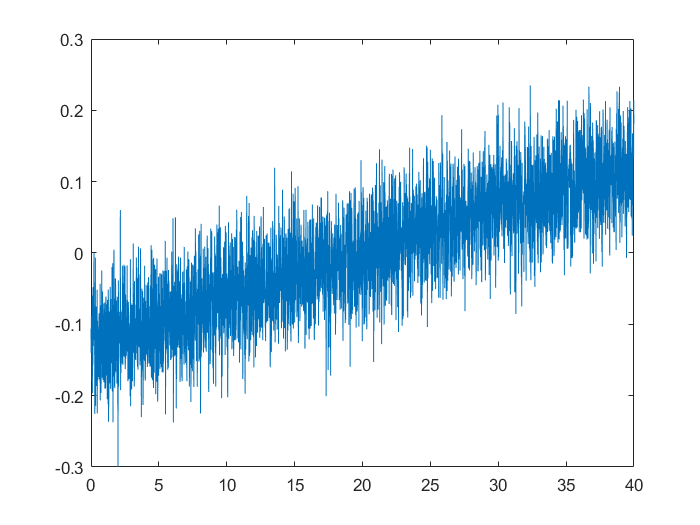

%accparams = accelparams('ConstantBias',0.09);
%IMU = imuSensor('SampleRate', fs, 'Accelerometer', accparams);
IMU = imuSensor('SampleRate', fs);

[accelerometerReadings,gyroscopeReadings] = IMU(accBody, angVelBody);

accelerometerReadings = accelerometerReadings + sigma_acceleration * randn(size(accelerometerReadings));
figure;
plot(timeVector, -accelerometerReadings(:, 1));

% subplot(1, 2, 1);
% plot(timeVector, accelerometerReadings);

## Generate Magnetometer data

model = @magnetic_model;

magnetometerData = cell(N, 1);
parfor iter = 1 : N
    magnetometerReadings = zeros(numSamples, 3);
    for i = 1 : size(pos, 1)
        [~, magnetometerReadings(i, 1)] = magnetometer(model, pos(i, 1) - sensor_spacing, sigma_magnetometer);
        [~, magnetometerReadings(i, 2)] = magnetometer(model, pos(i, 1), sigma_magnetometer);
        [~, magnetometerReadings(i, 3)] = magnetometer(model, pos(i, 1) + sensor_spacing, sigma_magnetometer);
    end
    magnetometerData{iter} = magnetometerReadings;
end



## EKF Setup

XData = cell(N, 1);
PData = cell(N, 1);
XData_NoUpd = cell(N, 1);
PData_NoUpd = cell(N, 1);


t = now;
d = datetime(t,'ConvertFrom','datenum')

d = datetime
   2021-11-13 20:44:46


% run with iteration
parfor iter = 1 : N
    magnetometerReadings = magnetometerData{iter};
    p = polyfit([init_pos(1)-sensor_spacing, init_pos(1), init_pos(1)+sensor_spacing], 1e6*magnetometerReadings(1, :), 2);
    initialStateGuess = [init_pos(1); init_vel(1); p.'];
    obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess, 'HasAdditiveProcessNoise', false, ...
        'StateTransitionJacobianFcn', @StateTransitionJacobianFcn);
    % obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess, 'HasAdditiveProcessNoise', false);
    obj.StateCovariance = diag([1e-2, 1e-4, 0.01, 0.01, 0.01]);
    
    obj.ProcessNoise = diag([sigma_acceleration^2, 1e-4, 1e-4, 1e-2, 1e-1, 1e-1]);
    obj.MeasurementNoise = sigma_magnetometer^2 * eye(3);
    
    X = zeros(numSamples, 5);
    P = zeros(numSamples, 5 , 5);
    X(1, :) = initialStateGuess;
    P(1, :, :) = diag([0.1, 0.1, 0.1, 0.1, 0.1]);
    
    X_NoUpd = zeros(numSamples, 5);
    P_NoUpd = zeros(numSamples, 5 , 5);
    X_NoUpd(1, :) = initialStateGuess;
    P_NoUpd(1, :, :) = diag([0.1, 0.1, 0.1, 0.1, 0.1]);
    
    % start from the second
    for i = 1 : numSamples - 1
        predict(obj, -accelerometerReadings(i, 1));
        correct(obj, magnetometerReadings(i + 1, :).', sensor_spacing);
        X(i + 1, :) = obj.State.';
        P(i + 1, :, :) = obj.StateCovariance;
    end
    
    XData{iter} = X;
    PData{iter} = P;

end




parfor iter = 1 : N
    magnetometerReadings = magnetometerData{iter};
    p = polyfit([init_pos(1)-sensor_spacing, init_pos(1), init_pos(1)+sensor_spacing], 1e6*magnetometerReadings(1, :), 2);
    initialStateGuess = [init_pos(1); init_vel(1); p.'];
    obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess, 'HasAdditiveProcessNoise', false, ...
        'StateTransitionJacobianFcn', @StateTransitionJacobianFcn);
    % obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess, 'HasAdditiveProcessNoise', false);
    obj.StateCovariance = diag([1e-2, 1e-4, 0.01, 0.01, 0.01]);
    
    obj.ProcessNoise = diag([sigma_acceleration^2, 1e-4, 1e-4, 1e-2, 1e-1, 1e-1]);
    obj.MeasurementNoise = sigma_magnetometer^2 * eye(3);
        
    X_NoUpd = zeros(numSamples, 5);
    P_NoUpd = zeros(numSamples, 5 , 5);
    X_NoUpd(1, :) = initialStateGuess;
    P_NoUpd(1, :, :) = diag([0.1, 0.1, 0.1, 0.1, 0.1]);
    
    % start from the second
    for i = 1 : numSamples - 1
        predict(obj, -accelerometerReadings(i, 1));
        X_NoUpd(i + 1, :) = obj.State.';
        P_NoUpd(i + 1, :, :) = obj.StateCovariance;
    end
    

    XData_NoUpd{iter} = X_NoUpd;
    PData_NoUpd{iter} = P_NoUpd;
end



## Statistics

% absPositionError = zeros(numSamples, N);
% stdPositionError = zeros(numSamples, N);
% absVelError      = zeros(numSamples, N);
% stdVelError      = zeros(numSamples, N);
% for iter = 1 : N
%     absPositionError(:, iter) = abs(XData{iter}(:, 1) - pos(:, 1));
%     stdPositionError(:, iter) = sqrt(PData{iter}(:, 1, 1));
%     absVelError(:, iter) = abs(XData{iter}(:, 2) - vel(:, 1));
%     stdVelError(:, iter) = sqrt(PData{iter}(:, 2, 2));
% end

[absPositionError,stdPositionError, absVelError, stdVelError] = calc_error(XData, PData, pos, vel, numSamples, N);
[absPositionError_NoUpd,stdPositionError_NoUdp, absVelError_NoUdp, stdVelError_NoUdp] = calc_error(XData_NoUpd, PData_NoUpd, pos, vel, numSamples, N);

## Plot error in position/velocity estimation

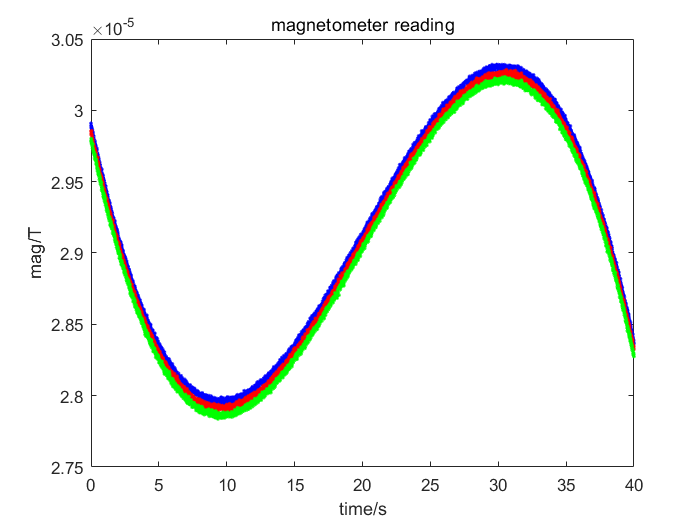

figure;
plot(timeVector,magnetometerData{1}(:,1),'b.',...
     timeVector,magnetometerData{1}(:,2),'r.',...
     timeVector,magnetometerData{1}(:,3),'g.')';
xlabel('time/s');
ylabel('mag/T');
title('magnetometer reading');

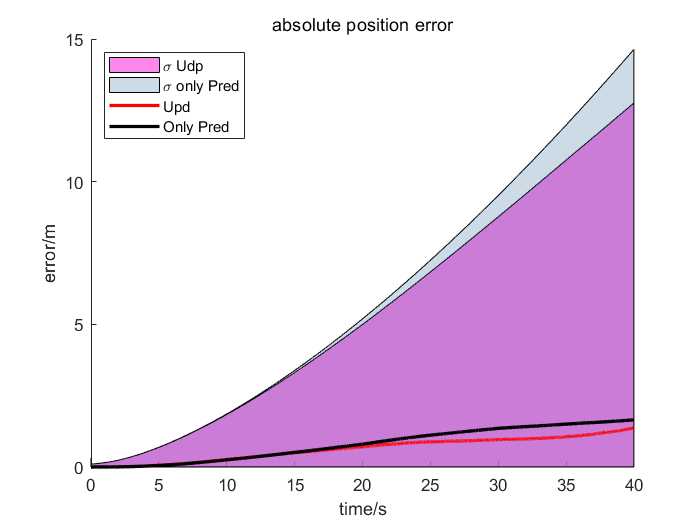


figure;
hold on;
% Udp
curve1 =  stdPositionError;
curve2 =  zeros(size(absPositionError));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0.9882 0.4157 0.9020], 'DisplayName','\sigma Udp');
h.FaceAlpha = 0.8;

curve1 =  stdPositionError_NoUdp;
curve2 =  zeros(size(absPositionError_NoUpd));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0 0.3 0.5], 'DisplayName','\sigma only Pred');
h.FaceAlpha = 0.2;

plot(timeVector, absPositionError, 'r','LineWidth', 2, 'DisplayName','Upd');
plot(timeVector, absPositionError_NoUpd, 'k','LineWidth', 2, 'DisplayName','Only Pred');
xlabel('time/s');
ylabel('error/m');
title('absolute position error');
legend('Location','northwest');

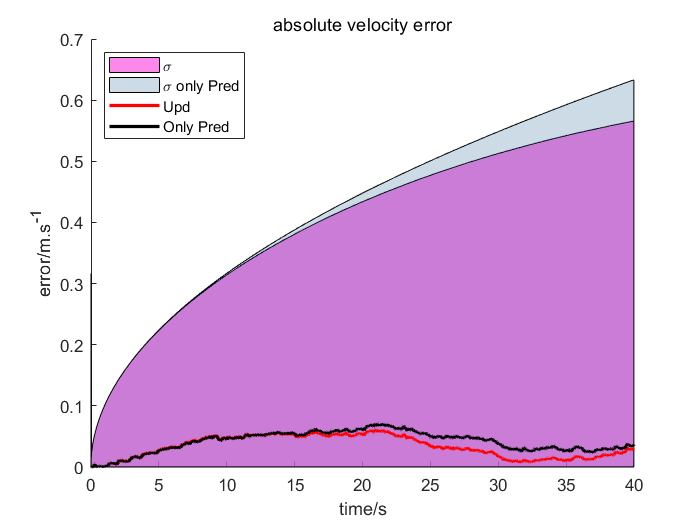


figure;
hold on;
curve1 =  stdVelError;
curve2 =  zeros(size(absVelError));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0.9882 0.4157 0.9020], 'DisplayName','\sigma');
h.FaceAlpha = 0.8;

curve1 =  stdVelError_NoUdp;
curve2 =  zeros(size(absVelError_NoUdp));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0 0.3 0.5], 'DisplayName','\sigma only Pred');
h.FaceAlpha = 0.2;



plot(timeVector, absVelError, 'r', 'LineWidth', 2, 'DisplayName','Upd');
plot(timeVector, absVelError_NoUdp, 'k','LineWidth', 2, 'DisplayName','Only Pred');
xlabel('time/s');
ylabel('error/m.s^{-1}');
title('absolute velocity error');
legend('Location','northwest');

## Put everything in subplots